# 1 DoF controller

close all
clear
clc

Let's define our 1dof control architecture

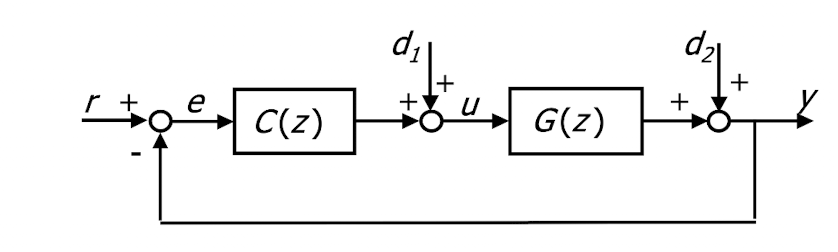

it is made by

- a plant G

- a controller C

- (a unitary feedback loop)

- 3 "input" r, d1, d2

- 3 "output" e, u, y

## Stability and responses

In order to analyze stability and performances of 1dof controller, we need to compute the transfer functions (tf) between every input and every output

### Responses

#### Effect of inputs on y

Since the system is linear, we can do superposition

Effect of r on y


$$Y(z) = \frac{G(z)C(z)}{1+ C(z)G(z)} R(z) \rightarrow W(z) = \frac{G(z)C(z)}{1+ C(z)G(z)} $$


Effect of d1 on y


$$Y(z) = \frac{G(z)}{1+ C(z)G(z)} D_1(z) \rightarrow W_1(z) = \frac{G(z)}{1+ C(z)G(z)} $$


Effect of d2 on y


$$Y(z) = \frac{1}{1+ C(z)G(z)} D_2(z) \rightarrow W_2(z) = \frac{1}{1+ C(z)G(z)} $$


Putting all together:


$$Y(z) = W(z) R(z) + W_1(z) D_1(z) + W_2(z) D_2(z)$$


#### Effect of inputs on e and u

We can do the same procedure with the other 2 outputs

We conclude that:


$$E(z) = W_2(z) R(z) - W_1(z) D_1(z) - W_2(z) D_2(z)   \\

U(z) = W_3(z) R(z) + W_2(z) D_1(z) - W_3(z) D_1(z) \\

\text{with} \quad W_3 = \frac{C(z)}{1+C(z)G(z)}$$


### Stability

In the previous section we have defined 4 tf: W, W1, W2, W3

Now we'll study stability starting from them

**Note: **we'll consider only well-posed feedback system, i.e.

- G(z) strictly proper

- C(z) proper or strictly proper

- (=> all the other tf (W,...) are proper)

**DEF: **a well-posed feedback system is **stable **if all the tf W, W1, W2, W3 are **BIBO stable**

Practically, we have stability if:

- there aren't instable z-p cancellations when the product L(z) = C(z)G(z)  is formed

- all the poles of the tf (i.e. the roots of the denominators) have magnitude **strictly less than one!!**

Moreover, if conditions are met we can **use just one of the four tf to analyze stability!!**

## **Exercises on stability and responses**

**Lab 1, problem 1**

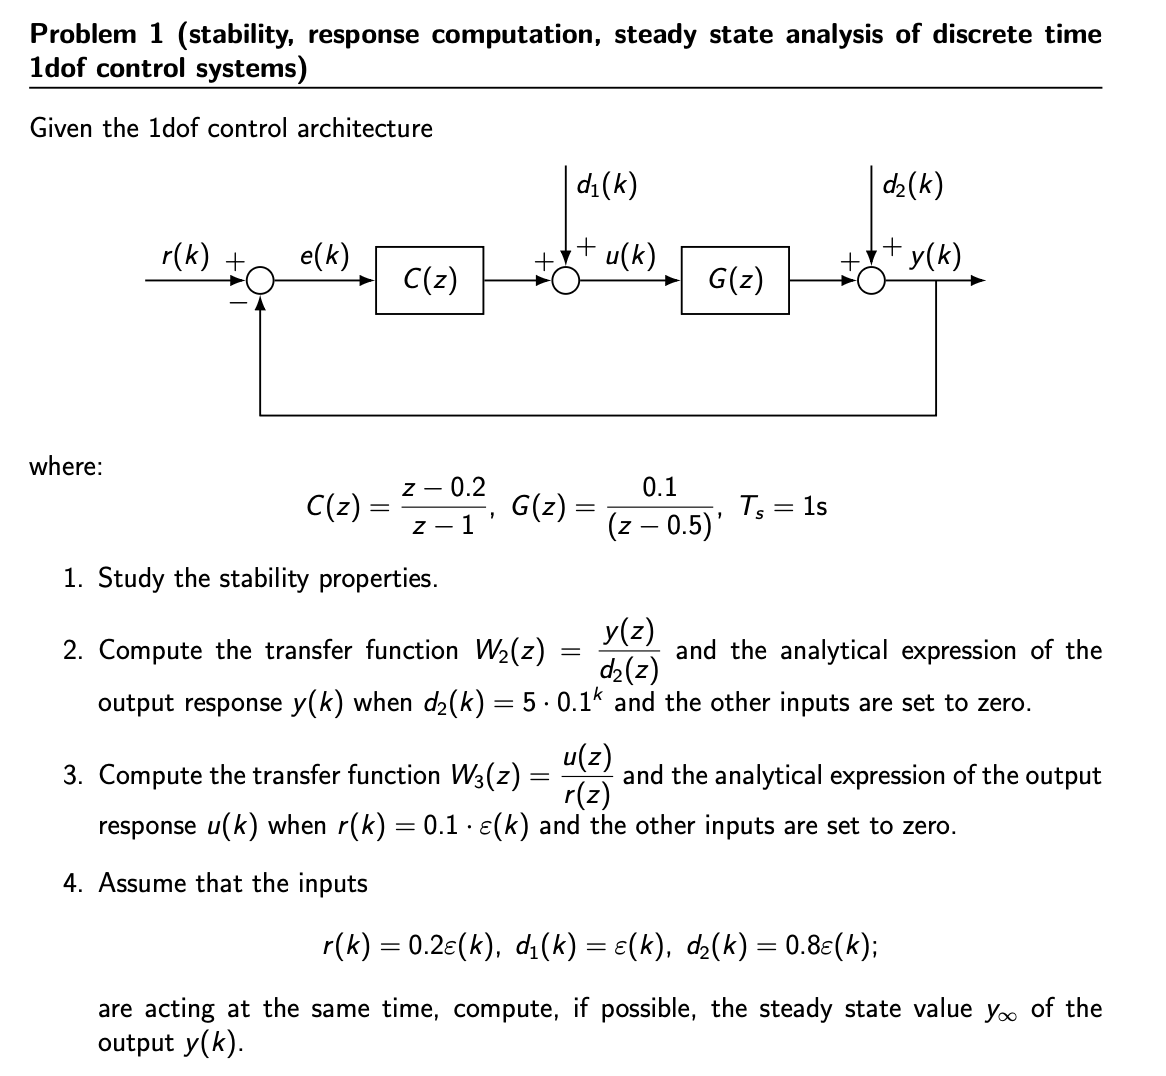

T = 1;
z = tf('z', T);
C = (z-0.2)/(z-1);
G = 0.1/(z-0.5);
L = C*G


L =
 
    0.1 z - 0.02
  -----------------
  z^2 - 1.5 z + 0.5
 
Sample time: 1 seconds
Discrete-time transfer function.


% stability
W2 = zpk(minreal(1/(1+L),1e-2))


W2 =
 
   (z-1) (z-0.5)
  ---------------
  (z-0.8) (z-0.6)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.


% we see that all the poles of W2 are < 1 => system is stable

% output response y(d2)
d2 = 5*z/(z-0.1);
Y_d2 = zpk(minreal(W2*d2,1e-2));
[nY_d2, dY_d2] = tfdata(Y_d2, 'v');
[rY_d2, pY_d2, kY_d2] = residuez(nY_d2, dY_d2)

rY_d2 =    -2.1429
    2.0000
    5.1429


pY_d2 =     0.8000
    0.6000
    0.1000


kY_d2 = 0


% output response u(r)
W3 = zpk(minreal(C/(1+L), 1e-2));
r = 0.1*z/(z-1);
U_r = W3*r


U_r =
 
  0.1 z (z-0.5) (z-0.2)
  ---------------------
  (z-0.8) (z-1) (z-0.6)
 
Sample time: 1 seconds
Discrete-time zero/pole/gain model.


[nU_r, dU_r] = tfdata(U_r, 'v');
[rU_r, pU_r, kU_r] = residuez(nU_r, dU_r)

rU_r =     0.5000
   -0.4500
    0.0500


pU_r =     1.0000
    0.8000
    0.6000


kU_r = 0


% output response & steady state
